## **Driver test program to check Clothoids library**

**Clothods list**

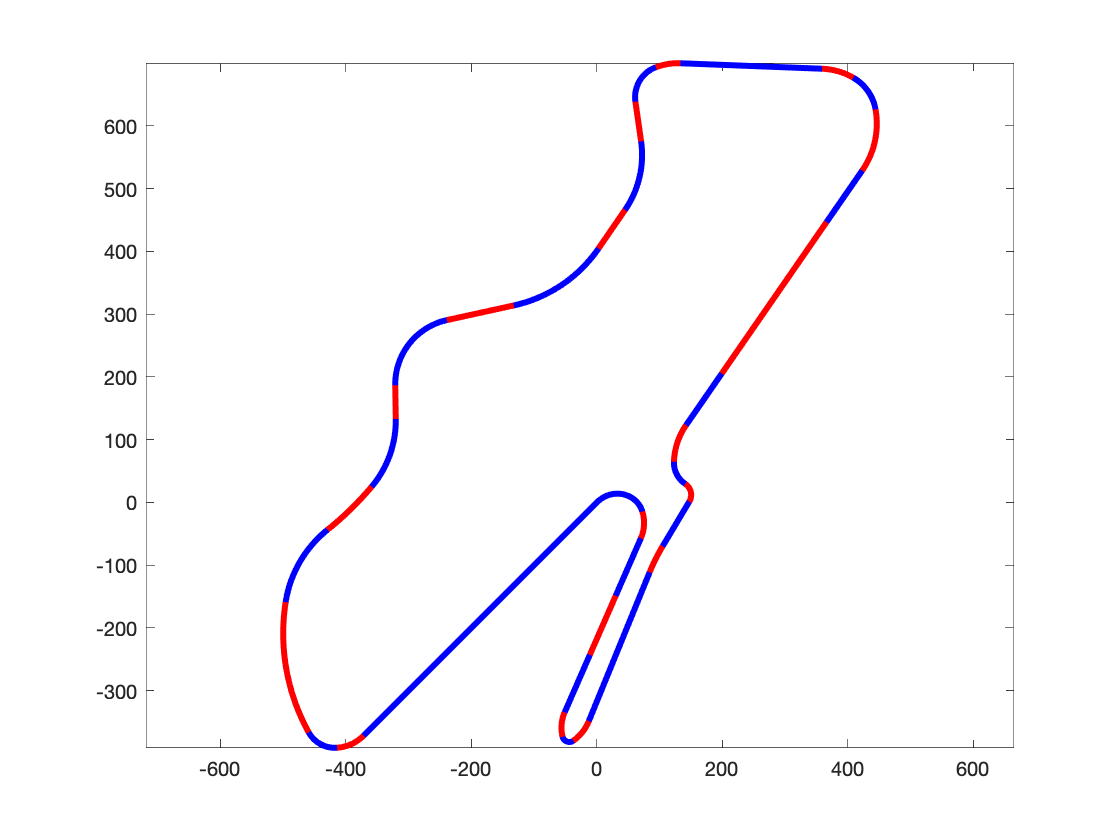

close all;

x0     = 0;
y0     = 0;
theta0 = -pi/2-pi/4;

S = ClothoidList();

to_rad  = @(a) a*pi/180;
addseg  = @(a,r) S.push_back( 1/r, 0, abs(to_rad(a)*r) );
addseg1 = @(l) S.push_back( 0, 0, l );

S.push_back( x0, y0, theta0, 0, 0, 525.734263 ); % first segment

addseg( 41.055964, -66.274364 );
addseg( 65.057808, -47.943560 );
addseg( 37.755853, -325.546776 );
addseg( 42.413220, -184.037842 );
addseg( 11.239181, 502.441450 );
addseg( 40.921332, 163.660348 );
addseg1( 53.626571 );
addseg( 78.502556, -104.702611 );
addseg1( 109.155437 );
addseg( 43.098645, 221.641281 );
addseg1( 74.378240 );
addseg( 42.657104, 154.218334 );
addseg1( 63.934654 );
addseg( 77.515196, -50.941620 );
addseg( 22.836057, -100.456722 );
addseg1( 225.840357 );
addseg( 27.645352, -108.328995 );
addseg( 50.144932, -72.814503 );
addseg( 44.659752, -131.266332 );
addseg1( 100 );
addseg1( 493.260988-200 );
addseg1( 100 );
addseg( 32.711821, 109.055920 );
addseg( 58.097199, 40.797507 );
addseg( 86.991602, -21.066189 );
addseg1( 82.732836 );
addseg( 8.630278, 308.551401 );
addseg1( 256.246033 );
addseg( 32.396042, -71.415019 );
addseg( 111.329243, -10.956416 );
addseg( 37.683624, -60.447512 );
addseg1( 100 );
addseg1( 302.799042-200 );
addseg1( 100 );
addseg( 40.770300, 61.373598 );

%addseg( 124.470619, 41.753224 );
S.push_back_G1( x0, y0, theta0); % close curve

S.plot();
axis equal